# Nonlinear building Model under Seismic Excitation

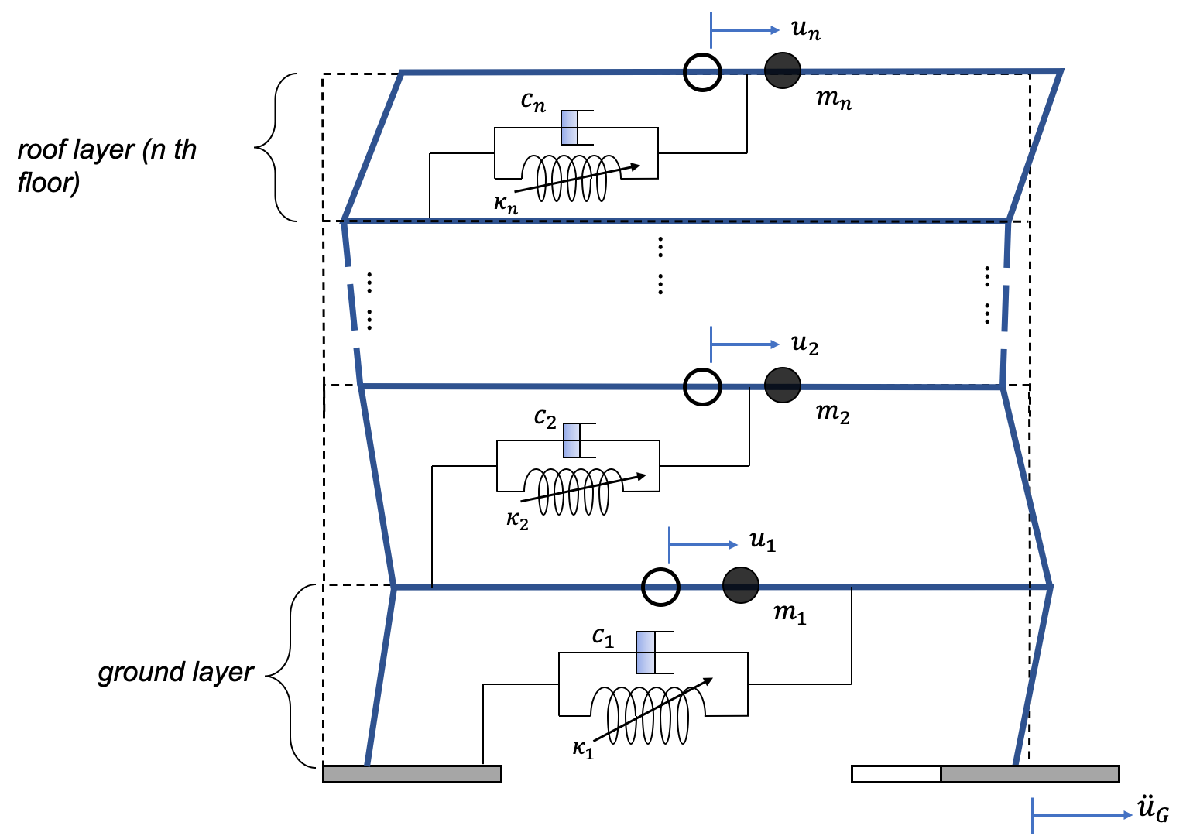

## Generate model

n = 10;
m = 7;
k = 4555;
c = 90;
kappa2 = 0;
kappa3 = 0;

[M,C,K,fnl] = build_model(n,m,c,k,kappa2,kappa3);

## Dynamical system setup 

We consider the stochastic forced system


$$\mathbf{M \ddot{u}}+\mathbf{C \dot{u}}+\mathbf{K u}+\mathbf{F}_{nl}(\mathbf{u},\mathbf{\dot{u}})=\mathbf{G \ddot{u}_{G}}$$


The 1-Dimensional model with n degree-of-freedom is forced by the ground movement in horizontal direction ${\ddot{\mathbf{u}} }_{\mathbf{G}}$ and it is assumed that only horizontal displacement is considered and no vertical motion caused by earthquake. The nonlinearities are captured by those nonlinear stiffness between storeys. 

The displacement vector and forcing vector are given by:

                                                    
$$\mathbf{u}=[u_1\,,u_2,\,...\,u_n]\\$$


                                                    
$$\mathbf{G}=[-m_1\,,-m_2,\,...\,-m_n]$$


nRealization=20;
resol = 1;
T0=resol*100; %% PSD frequency domain resolution is ~ 1/T0
nPoints=resol*2^14; %% control the accuracy of numerical differential equation
epsilon=50; %% forcing magnitude
[filterPSD,forcingdof,stochastic_f] = build_stochasticF(m,epsilon,n);

We assume the acceleration of the ground motion ${\ddot{\mathbf{u}} }_{\mathbf{G}}$ formulated by

                                            
$$\ddot{a}(t)+c_1\dot{a}(t)+c_0(t)a(t)=\epsilon I(t) \xi (t)$$


where $c_1 (t) =c_1$ , $c_0(t) =c_0
$ , $I(t) = I$ are constants and $\xi (t)$ is Gaussian white noise 

We take the velocity of $a$ to be the ground acceleration:

                                                        
$$\mathbf{\dot{u}}_{G}=a \ \ \ \mathbf{\ddot{u}}_{G}=\dot{a}$$


setting for the SDE solver and allocate desired output PSD pairs

SS = StochasticSystem();

set(SS,'filterPSD',filterPSD,'linear',true)
set(SS,'M',M,'C',C,'K',K,'fnl',fnl,'gFactor',-m);
set(SS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
set(SS.SSOptions,'ssMethod','indirect')
SS.add_random_forcing(nRealization, T0, nPoints,forcingdof);

clusterRun=true; %% if the script is run on local or cluster.
method="filter ImplicitMidPoint";
PSDpair=[n,n];

## Solve full system

[V, D, W] = SS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 3.766559e-02
modal damping ratio for 2 mode is 1.121554e-01
modal damping ratio for 3 mode is 1.841398e-01
modal damping ratio for 4 mode is 2.520109e-01
modal damping ratio for 5 mode is 3.142524e-01

 The first 10 eigenvalues are given as 
  -0.1436 + 3.8099i
  -0.1436 - 3.8099i
  -1.2733 +11.2810i
  -1.2733 -11.2810i
  -3.4322 +18.3203i
  -3.4322 -18.3203i
  -6.4286 +24.6858i
  -6.4286 -24.6858i
  -9.9962 +30.1979i
  -9.9962 -30.1979i



firts_res=abs(imag(D(1)));
SS.sdeImpTimeDisp = false;
[w,outputPSD] = SS.monte_carlo_average(method,PSDpair,nRealization,clusterRun);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).


## Calculation of linear response

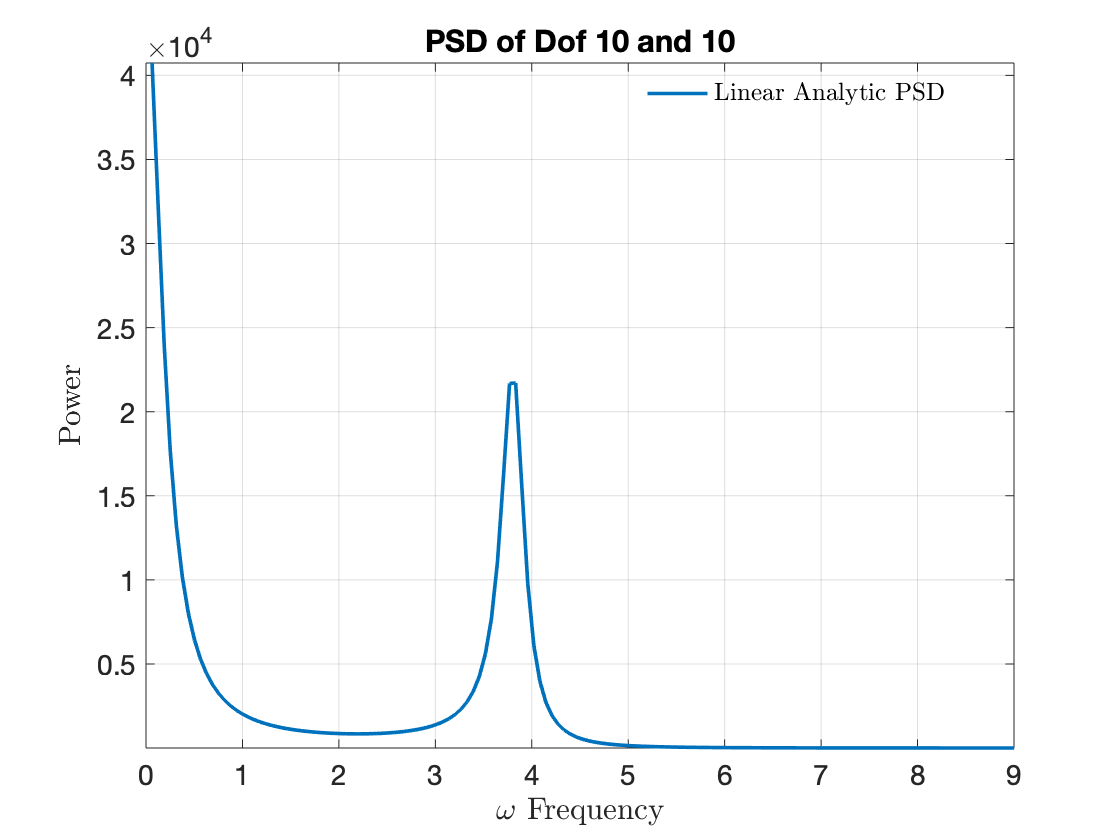

freq_range=[0 9];
[w_linear, linear_analytic]=SS.compute_linear_PSD(PSDpair,freq_range);

**Choose Master subspace (perform resonance analysis)**

S = SSM(SS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
% set(S.Options, 'reltol', 0.1,'notation','tensor')
masterModes = [1,2]; 
S.choose_E(masterModes);

(near) outer resonance detected for the following combination of master eigenvalues
     5     2
     6     3
     2     5
     3     6

These are in resonance with the follwing eigenvalues of the slave subspace
  -1.2733 +11.2810i
  -1.2733 +11.2810i
  -1.2733 -11.2810i
  -1.2733 -11.2810i

sigma_out = 69
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     1     2

These are in resonance with the follwing eigenvalues of the master subspace
  -0.1436 + 3.8099i
  -0.1436 - 3.8099i

sigma_in = 69


## Power Spectral Density using SSMs

Obtaining PSD from approximation order

Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 1.64E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 2.45E-02 MB
Manifold computation time at order 4 = 00:00:00
Estimated memory usage at order  4 = 3.16E-02 MB
Manifold computation time at order 5 = 00:00:00
Estimated memory usage at order  5 = 4.32E-02 MB
Compute the PSD through SSM of order 5
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 2).


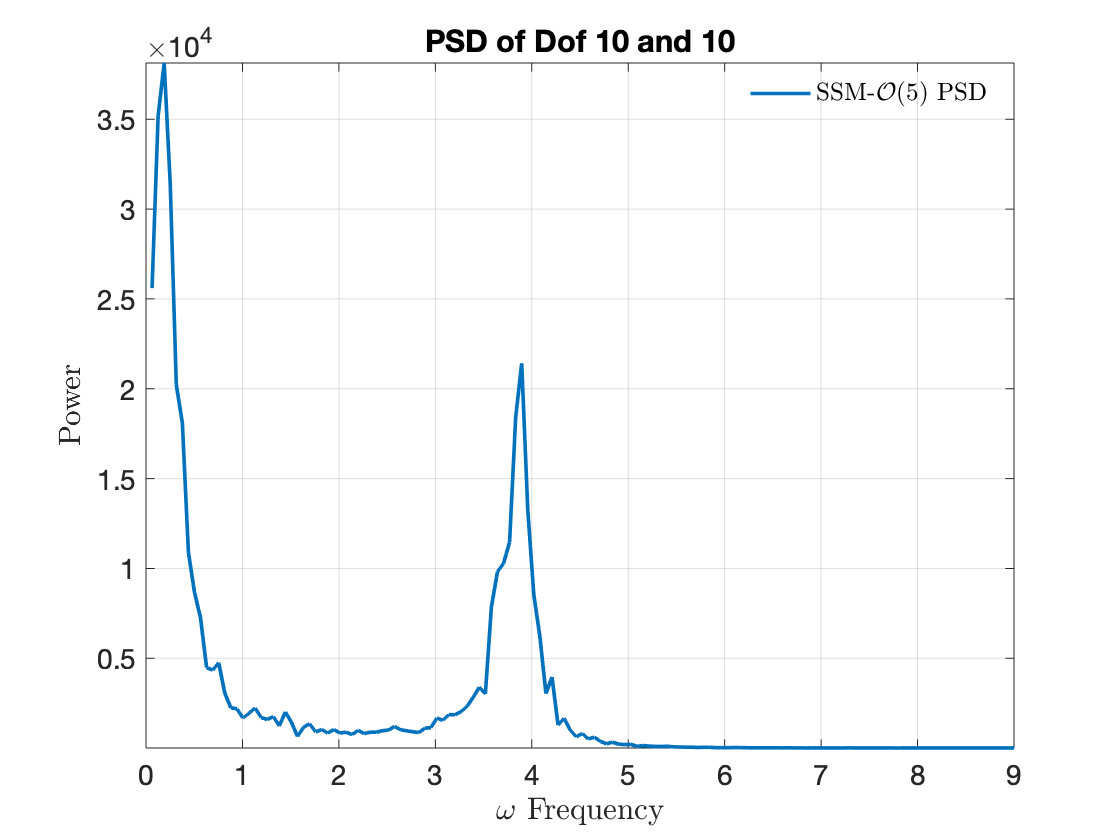

order = 5;
 % depend on res
S.ssmSEulerTimeDisp = false;
[wss,ssmPSD]=S.extract_PSD(PSDpair, order,'filter hen',freq_range,clusterRun);

## Compare the results of SSM, full system response and linear response

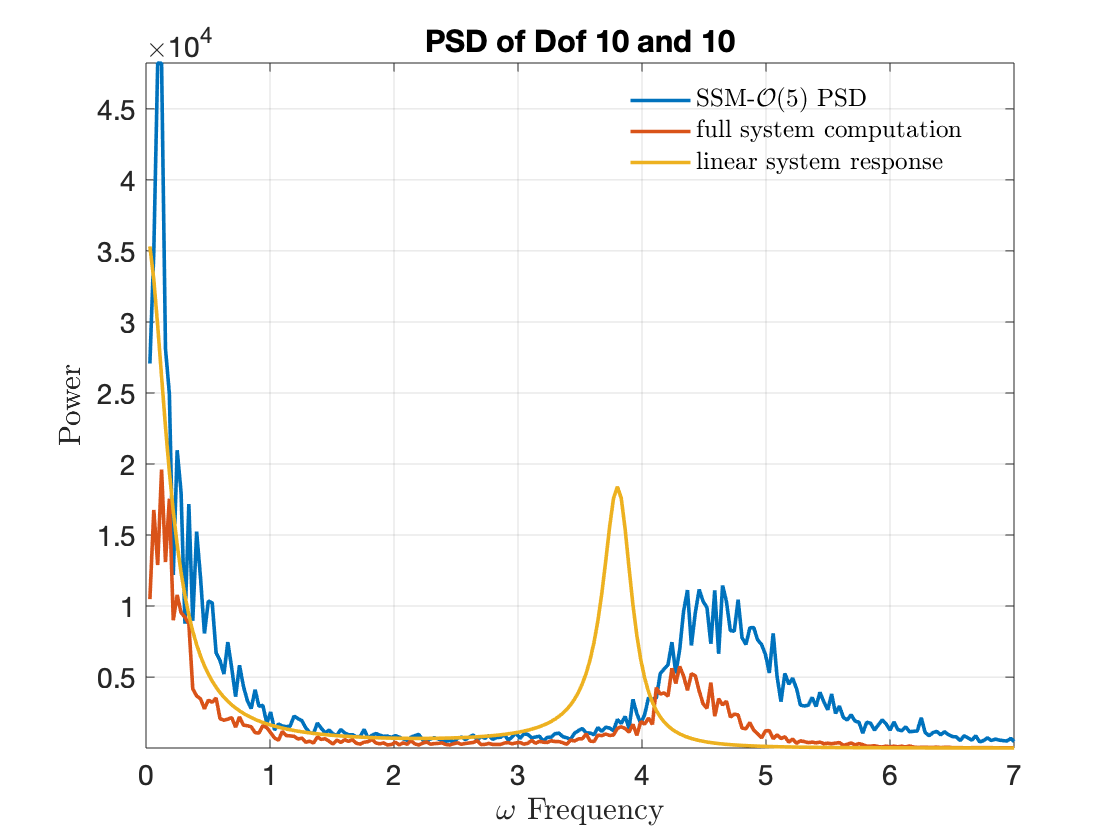

% we may have the option to display psd: w_range
% try diff epsilon
% figure
% plot(wss,ssmPSD,'linewidth',1)
% hold on
% plot(w,outputPSD(1,:),'linewidth',1)
% hold on
% plot(w_linear,linear_analytic(1,:),'linewidth',1)
% xline(firts_res,'-',{'First Resonance'},'linewidth',1.5);
% legend('SSM','nonlinear simulation','linear analytic')
% xlim(freq_range);
% grid on
plot_all_PSD(w,ssmPSD,outputPSD,linear_analytic,order,PSDpair,freq_range)